# MAE384 Group Project

Initialize common variables and functions:

% Beta is the Transmission Rate
% Gamma is the Recovery Rate
% S(t) is # of Susceptible Individuals at t
% I(t) is # of Infected Individuals at t
% R(t) is # of Recovered Individuals at t
dSdt = @(S,I,R,beta) (-beta./(S+I+R)).*S.*I;
dIdt = @(S,I,R,beta,gamma) (beta./(S+I+R)).*S.*I - gamma.*I;
dRdt = @(I,gamma) gamma.*I;

# Part 1. Runge-Kutta

## 1.

%Parameters
h1 = 1; %Time step; Days
t0 = 0; %Initial Time
s0 = 990; %Initial Susceptible Indiviudals
i0 = 10; %Initial Infected Individuals
r0 = 0; %Initial Recovered Individuals
T = 100; %Total Simulation Time, Days
betaFlu = 0.3;
gammaFlu = 0.1;
betaCovid = 1;
gammaCovid = 0.1;
betaMeas = 2;
gammaMeas = 0.2;

Flu = [0.3,0.1]; %Beta,Gamma
Covid = [1,0.1]; %Beta,Gamma
Meas = [2,0.2]; %Beta,Gamma
Dis = [Flu;Covid;Meas];


%Solving
t1 = 0; %Time variable part 1, days
N = (T - t0)/h1; %Number of Steps
S = zeros(3,N+1);
S(:,1) = s0;
I = zeros(3,N+1);
I(:,1) = i0;
R = zeros(3,N+1);
R(:,1) = r0;
for k = 1:3
    beta(k) = Dis(k,1);
    gamma(k) = Dis(k,2);
    for i = 1:N
        k1 = SIRModel(S(k,i),I(k,i),R(k,i),beta(k),gamma(k));
        k2 = SIRModel(S(k,i) + 0.5*h1*k1(1),I(k,i) + 0.5*h1*k1(2),R(k,i) + 0.5*h1*k1(3),beta(k),gamma(k));
        k3 = SIRModel(S(k,i) + 0.5*h1*k2(1),I(k,i) + 0.5*h1*k2(2),R(k,i) + 0.5*h1*k2(3),beta(k),gamma(k));
        k4 = SIRModel(S(k,i) + h1*k3(1),I(k,i) + h1*k3(2),R(k,i) + h1*k3(3),beta(k),gamma(k));
        S(k,i+1) = S(k,i) + (1/6)*(k1(1) + 2*k2(1) + 2*k3(1) + k4(1))*h1;
        I(k,i+1) = I(k,i) + (1/6)*(k1(2) + 2*k2(2) + 2*k3(2) + k4(2))*h1;
        R(k,i+1) = R(k,i) + (1/6)*(k1(3) +2*k2(3) + 2*k3(3) + k4(3))*h1;
    end
end

## 2.

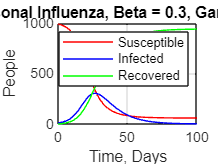

t = 0:100;
%Flu
plot(t,S(1,:),'r',t,I(1,:),'b',t,R(1,:),'g')
hold on;
grid on;
title('Seasonal Influenza, Beta = 0.3, Gamma = 0.1');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

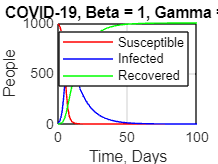


%Covid-19
plot(t,S(2,:),'r',t,I(2,:),'b',t,R(2,:),'g')
hold on;
grid on;
title('COVID-19, Beta = 1, Gamma = 0.1');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

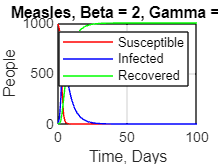


%Measles
plot(t,S(3,:),'r',t,I(3,:),'b',t,R(3,:),'g')
hold on;
grid on;
title('Measles, Beta = 2, Gamma = 0.2');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

# Part 2: Interpolation

% Base case of Seasonal Influenza
beta = 0.3;
gamma = 0.1;
h2 = 2;
t = 0:100;

% linear
S2lin = zeros(1, N + 1);
S2lin(1, 1) = s0;
I2lin = zeros(1, N + 1);
I2lin(1, 1) = i0;
R2lin = zeros(1, N + 1);
R2lin(1, 1) = r0;
for i = 3:2:(N + 1)
    S2lin(i) = S(1, i);
    I2lin(i) = I(1, i);
    R2lin(i) = R(1, i);
end
for i = 2:2:(N + 1)
    S2lin(i) = S2lin(i - 1) + (S2lin(i + 1) - S2lin(i - 1)) / 2;
    I2lin(i) = I2lin(i - 1) + (I2lin(i + 1) - I2lin(i - 1)) / 2;
    R2lin(i) = R2lin(i - 1) + (R2lin(i + 1) - R2lin(i - 1)) / 2;
end

Nint = N / 2;
for k = 2:2:(N + 1)
    EL2Slin = sqrt(sum((S2lin(k) - S(1, k))^2) / Nint);
    EL2Ilin = sqrt(sum((I2lin(k) - I(1, k))^2) / Nint);
    EL2Rlin = sqrt(sum((R2lin(k) - R(1, k))^2) / Nint);
end

% quadratic
S2quad = zeros(1, N + 1);
S2quad(1, 1) = s0;
I2quad = zeros(1, N + 1);
I2quad(1, 1) = i0;
R2quad = zeros(1, N + 1);
R2quad(1, 1) = r0;
for i = 3:2:(N + 1)
    S2quad(i) = S(1, i);
    I2quad(i) = I(1, i);
    R2quad(i) = R(1, i);
end
for i = 2:2:(N + 1)
    if (i == 2)
        Sb0 = S2quad(i - 1);
        Sb1 = (S2quad(i + 1) - S2quad(i - 1)) / 2;
        Sb2 = (((S2quad(i + 3) - S2quad(i + 1)) / 2) - ((S2quad(i + 1) - S2quad(i - 1)) / 2)) / 4;
        S2quad(i) = Sb0 + Sb1 + (Sb2 * -1);
        Ib0 = I2quad(i - 1);
        Ib1 = (I2quad(i + 1) - I2quad(i - 1)) / 2;
        Ib2 = (((I2quad(i + 3) - I2quad(i + 1)) / 2) - ((I2quad(i + 1) - I2quad(i - 1)) / 2)) / 4;
        I2quad(i) = Ib0 + Ib1 + (Ib2 * -1);
        Rb0 = R2quad(i - 1);
        Rb1 = (R2quad(i + 1) - R2quad(i - 1)) / 2;
        Rb2 = (((R2quad(i + 3) - R2quad(i + 1)) / 2) - ((R2quad(i + 1) - R2quad(i - 1)) / 2)) / 4;
        R2quad(i) = Rb0 + Rb1 + (Rb2 * -1);
    else
        Sb0 = S2quad(i - 3);
        Sb1 = (S2quad(i - 1) - S2quad(i - 3)) / 2;
        Sb2 = (((S2quad(i + 1) - S2quad(i - 1)) / 2) - ((S2quad(i - 1) - S2quad(i - 3)) / 2)) / 4;
        S2quad(i) = Sb0 + (Sb1 * 3) + (Sb2 * 3);
        Ib0 = I2quad(i - 3);
        Ib1 = (I2quad(i - 1) - I2quad(i - 3)) / 2;
        Ib2 = (((I2quad(i + 1) - I2quad(i - 1)) / 2) - ((I2quad(i - 1) - I2quad(i - 3)) / 2)) / 4;
        I2quad(i) = Ib0 + (Ib1 * 3) + (Ib2 * 3);
        Rb0 = R2quad(i - 3);
        Rb1 = (R2quad(i - 1) - R2quad(i - 3)) / 2;
        Rb2 = (((R2quad(i + 1) - R2quad(i - 1)) / 2) - ((R2quad(i - 1) - R2quad(i - 3)) / 2)) / 4;
        R2quad(i) = Rb0 + (Rb1 * 3) + (Rb2 * 3);
    end
end

for k = 2:2:(N + 1)
    EL2Squad = sqrt(sum((S2quad(k) - S(1, k))^2) / Nint);
    EL2Iquad = sqrt(sum((I2quad(k) - I(1, k))^2) / Nint);
    EL2Rquad = sqrt(sum((R2quad(k) - R(1, k))^2) / Nint);
end

EL2 = [EL2Slin EL2Ilin EL2Rlin; EL2Squad EL2Iquad EL2Rquad];
% from looking at the EL2 matrix, it's clear that the quadratic
% interpolation provides smaller errors. for example, compare EL2 of the
% susceptible population for the linear and quadratic, and notice that the
% 2nd row (quadratic) is 0.0155 * 10^-3 which is smaller than the 1st row (linear),
% which is 0.1750 * 10^-3.